clc % clear command window
clear % clear MATLAB workspace

**Set up robot control system**

% create arduino ref-objects
    [robotArduino, rawRangeIn, blinkLED]= SETUPARDUINO('COM8');
    
% Turn on board LED on and off to signal program has started
    Blink(robotArduino,blinkLED,3);
    disp('Warning! Position Servo Active! ');

Warning! Position Servo Active! 


    
% Configuration test loop to collect n points
    nTests = input(['Enter number of range test position, '...
        'followed by enter: ']);
  clc
    
% Create a variable to hold experimental position data
    positionData = zeros(nTests,2);
    
r = rateControl(0.25);
reset(r);

**Run Robot Control Loop**

controlFlag = 1;                    % create a loop control
while (controlFlag < nTests+1)      % loop till ntests data captured
    
    rangeData = SENSE(robotArduino, rawRangeIn);         % collect desired position from operator
    THINK(); % compute what the robot should do next    
    ACT(); % command robot actuators
    
    % store experimental commanded versus actual data
    positionData(controlFlag,1) = input('Enter actual distance(cm): ');
    gtest = input('move Sonar to new range, type G and then hit Enter','s')
    positionData(controlFlag,2) = rangeData;
    Blink(robotArduino, blinkLED, 1);
    waitfor(r);                     % wait for code cycle to complete
    controlFlag = controlFlag + 1;  %increment loop
end

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

Sense


gtest = 'G'

**Mission data processing**

For many robot appliaction, you will need to post-process the data collected after the mission. Here we will plot the desied versus actual motor positions.

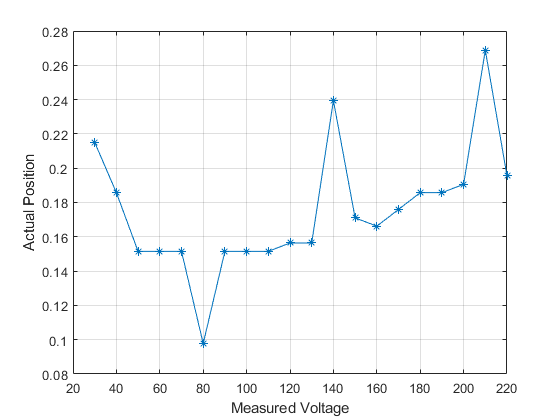

% Plot and store commanded position data vs. actual position
plot(positionData(:,1), positionData(:,2), '-*')
xlabel('Measured Voltage')
ylabel('Actual Position')
grid

**Clean shut down**

finally, with most embedded robot controllers, it's good practice to put all actuators into a safe postion and then release all control objects and shut down all communication paths. This keeps systems from jamming when you want to run again.

% Stop program and clean up the connection to Arduino when no longer needed
clc
disp('Arduino program has ended');

Arduino program has ended



clear robotArduino
beep           % play system sound to let user know program is ended

**Robot Functions**

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. It requires which COM Port your Arduino is attached to as its
% input and returns an Arduino object called robotArduino. 

% Creates a global arduino object so that it can be used in functions 
% a = arduino('setToYourComNumber','Uno',Libraries','Servo');
    robotArduino = arduino(COMPORT, 'Uno','Libraries','Servo');

% configure pin 13 as a digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino,blinkLED,'DigitalOutput');

% configure A0 pin as an analog input
    rawRangeIn = 'A2';
    configurePin(robotArduino, rawRangeIn, 'AnalogInput')
end

function [] = Blink(a,LED,n)
% Blink toggles Arduino a LED on and off to indicate program running input
% n is number of blinks
% no output is returned
    for bIndex = 1:n
        writeDigitalPin(a,LED,0);
        pause(0.2);
        writeDigitalPin(a,LED,1);
        pause(0.2);
    end
end

**Sense Function** (store all Sense related Local functions)

function rangeData = SENSE(robotArduino, rawRangeIn)
disp('Sense');
rangeData = readVoltage(robotArduino, rawRangeIn);
end

**Think Function **(store all Think related Local functions)

function THINK()
    % null function, not much thinking to do here
end

**Act Function **(store all Act related Local functions)

function ACT()
% null function    
end